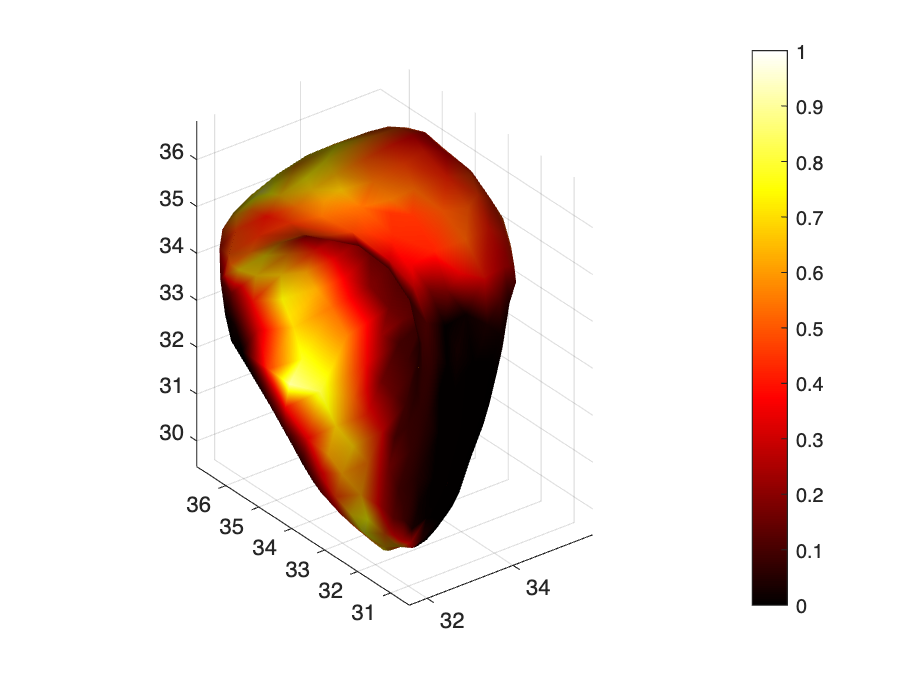

% T1 image * mask, then normalize by T1gd Max
% Load Data
nii_t1 = double(niftiread('data/T1_014_0000.nii.gz'));
nii_mask = niftiread('data/T1_014_label.nii.gz');
nii_t1gd = double(niftiread('data/T1Gd_014_0000.nii.gz'));

% Apply mask to T1 image (only visualize within region of interest)
masked_img = nii_t1 .* double(nii_mask);


% Normalize T1 image using max of T1Gd
max_t1gd = max(nii_t1gd(nii_mask > 0));  % max inside mask
nii_t1_norm = masked_img / max_t1gd;

% Generate surface from mask
% Threshold dark lumen region inside the aneurysm
threshold = 0.3 * max(masked_img(:));  % ~30% of max
lumen_mask = masked_img < threshold;

% Generate inner surface from lumen
fv = isosurface(lumen_mask, 0.5);


% Smooth the surface
fv = smoothpatch(fv, 1, 10);
% fv.vertices = laplacian_smooth(fv.vertices, fv.faces, 10, 0.5);

% Compute normals
normals = isonormals(nii_mask, fv.vertices);

% Set up interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1_norm,1), 1:size(nii_t1_norm,2), 1:size(nii_t1_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1_norm, 'linear', 'nearest');

% Sample intensity along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / norm(normals(i,:));
    
    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap hot;
colorbar;
clim([0 1]);  % normalized scale
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;

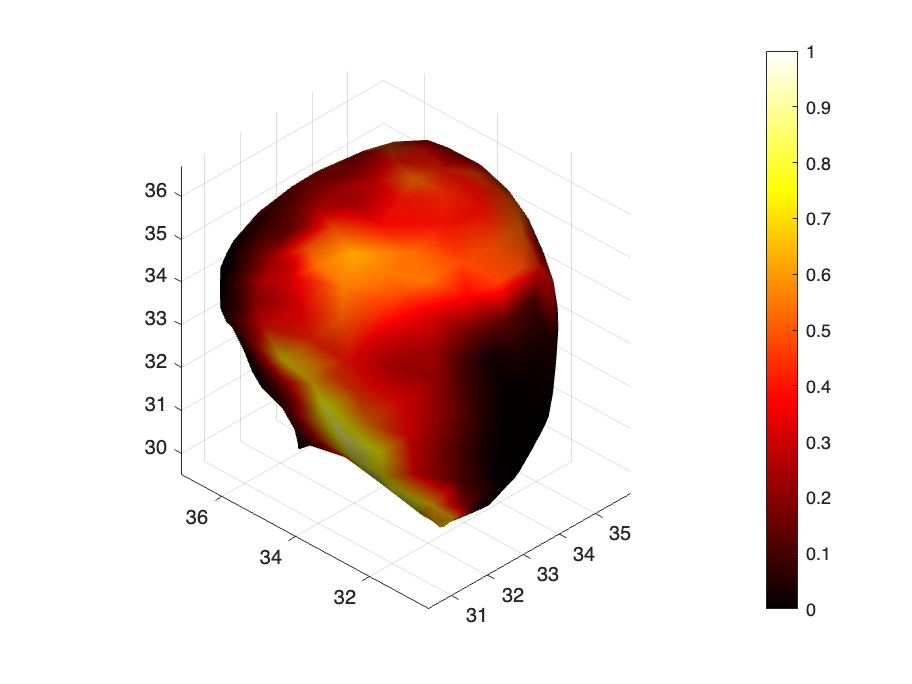

% T1 image * prediction, Normalized by T1gd Max
% Load Data
nii_t1 = double(niftiread('data/T1_014_0000.nii.gz'));
nii_mask = niftiread('data/T1_014_prediction.nii.gz');
nii_t1gd = double(niftiread('data/T1Gd_014_0000.nii.gz'));

% Apply mask to T1 image (only visualize within region of interest)
masked_img = nii_t1 .* double(nii_mask);


% Normalize T1 image using max of T1Gd
max_t1gd = max(nii_t1gd(nii_mask > 0));  % max inside mask
nii_t1_norm = masked_img / max_t1gd;

% Generate surface from mask
fv = isosurface(nii_mask, 0.5);

% Smooth the surface
fv = smoothpatch(fv, 1, 10);
% fv.vertices = laplacian_smooth(fv.vertices, fv.faces, 10, 0.5);

% Compute normals
normals = isonormals(nii_mask, fv.vertices);

% Set up interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1_norm,1), 1:size(nii_t1_norm,2), 1:size(nii_t1_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1_norm, 'linear', 'nearest');

% Sample intensity along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / norm(normals(i,:));
    
    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap hot;
colorbar;
clim([0 1]);  % normalized scale
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;

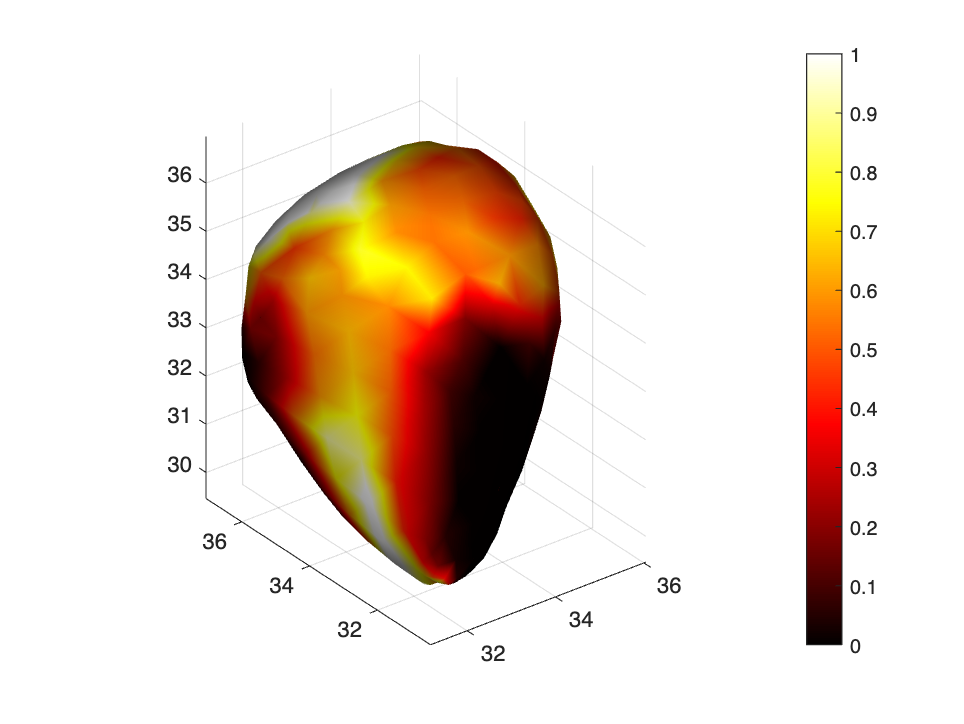

% T1GD image * mask, Normalized by T1gd Max
% Load Data
nii_t1gd = double(niftiread('data/T1Gd_014_0000.nii.gz'));
nii_mask = niftiread('data/T1_014_label.nii.gz');

% Apply mask to T1 image (only visualize within region of interest)
masked_img = nii_t1gd .* double(nii_mask);

% Normalize T1 image using max of T1Gd
max_t1gd = max(nii_t1gd(nii_mask > 0));  % max inside mask
nii_t1gd_norm = masked_img / max_t1gd;

% Generate surface from mask
fv = isosurface(nii_mask, 0.5);

% Smooth the surface
fv = smoothpatch(fv, 1, 10);
% fv.vertices = laplacian_smooth(fv.vertices, fv.faces, 10, 0.5);

% Compute normals
normals = isonormals(nii_mask, fv.vertices);

% Set up interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1gd_norm,1), 1:size(nii_t1gd_norm,2), 1:size(nii_t1gd_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1gd_norm, 'linear', 'nearest');

% Sample intensity along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / norm(normals(i,:));
    
    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize (mask*image, then normalized using max t1gd(current just t1))
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap hot;
colorbar;
clim([0 1]);  % since normalized by max
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;

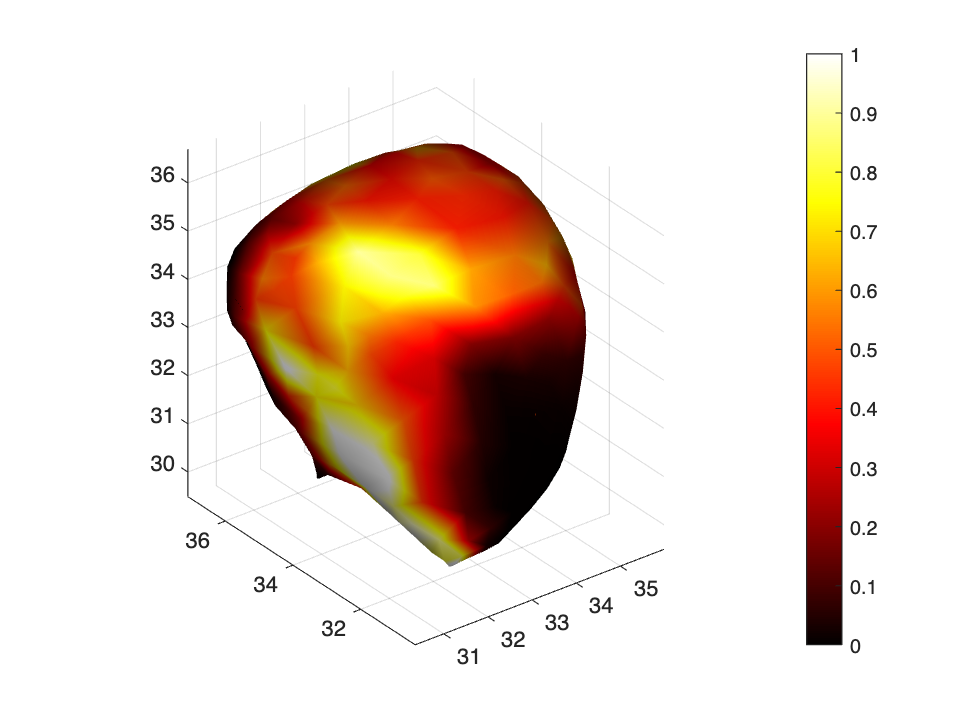

% T1GD image * prediction, Normalized by T1gd Max
% Load Data
nii_t1gd = double(niftiread('data/T1Gd_014_0000.nii.gz'));
nii_mask = niftiread('data/T1_014_prediction.nii.gz');

% Apply mask to T1 image (only visualize within region of interest)
masked_img = nii_t1gd .* double(nii_mask);

% Normalize T1 image using max of T1Gd
max_t1gd = max(nii_t1gd(nii_mask > 0));  % max inside mask
nii_t1gd_norm = masked_img / max_t1gd;

% Generate surface from mask
fv = isosurface(nii_mask, 0.5);

% Smooth the surface
fv = smoothpatch(fv, 1, 10);
% fv.vertices = laplacian_smooth(fv.vertices, fv.faces, 10, 0.5);

% Compute normals
normals = isonormals(nii_mask, fv.vertices);

% Set up interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1gd_norm,1), 1:size(nii_t1gd_norm,2), 1:size(nii_t1gd_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1gd_norm, 'linear', 'nearest');

% Sample intensity along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / norm(normals(i,:));
    
    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize (mask*image, then normalized using max t1gd(current just t1))
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap hot;
colorbar;
clim([0 1]);  % since normalized by max
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;

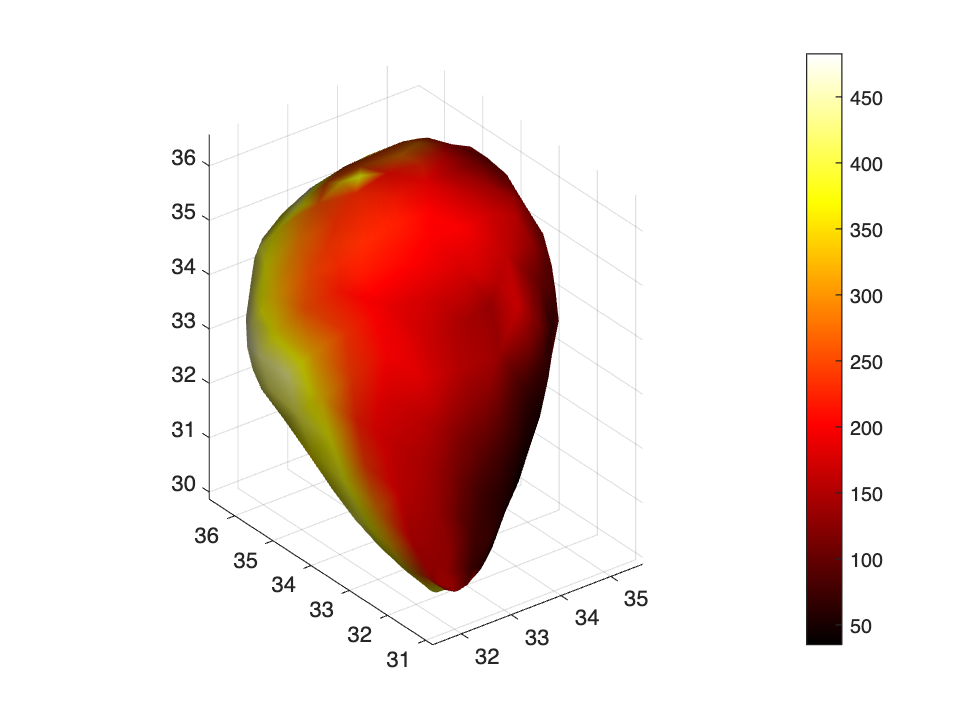

% T1 raw intensity

% addpath(genpath('/Users/clairexu/Desktop/UW/MedImage/smoothpatch_version1b'));
% rmpath('/Users/clairexu/Desktop/UW/MedImage/smoothpatch_version1b');
% rmpath('/Users/clairexu/Library/Application Support/MathWorks/MATLAB Add-Ons/Collections/Smooth Triangulated Mesh');

% Load Data
nii_img = niftiread('data/T1_014_image.nii.gz');
nii_label = niftiread('data/T1_014_label.nii.gz');
info = niftiinfo('data/T1_014_image.nii.gz');

% Generate Surface Mesh
fv = isosurface(nii_label, 0.5);  % extract boundary at label=1

% Smooth the surface if smoothpatch is compiled
fv = smoothpatch(fv, 1, 10);
fv.vertices = laplacian_smooth(fv.vertices, fv.faces, 10, 0.5);

% Compute Normals
normals = isonormals(nii_label, fv.vertices);

% Set up Interpolator (raw T1, no normalization)
[x, y, z] = ndgrid(1:size(nii_img,1), 1:size(nii_img,2), 1:size(nii_img,3));
interpFunc = griddedInterpolant(x, y, z, double(nii_img), 'linear', 'nearest');

% Sample Intensity along Normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / norm(normals(i,:));
    
    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize with raw intensity
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap hot;
colorbar;
clim([min(max_sis), max(max_sis)]);  % dynamic range for raw intensity
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;